# [线性调频信号脉冲压缩的匹配滤波实现](https://blog.csdn.net/qq_45732223/article/details/109322235#9_140)

## 线性调频信号的匹配滤波器输出

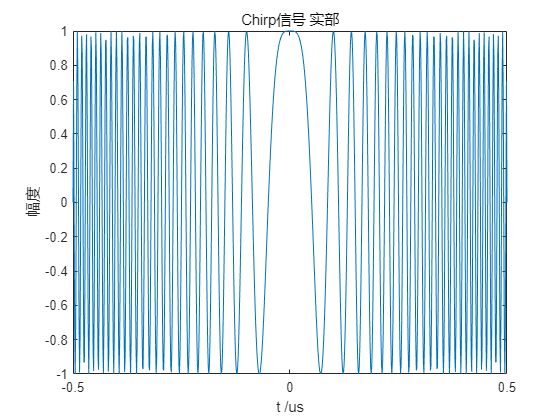

clear all;
close all;
clc;
%%******************* 线性调频与脉冲压缩 ********************%%
set(0,'defaultfigurecolor','w'); %设置MATLAB的图形窗口背景为白色
%% 线性调频信号参数设置
T = 1e-6;      %时宽
B = 200e6;     %带宽
Fs = 4*B;      %采样率

K = B/T;                          %调谐频率
N = round(T/(1/Fs) );             %采样点数，四舍五入
%% 产生线性调频信号
t = linspace( -T/2 ,T/2 ,N);
st = ( abs(t) < T/2 ) .* exp( 1j * pi * K * t.^2 ); 
phase = pi * K * t.^2;          %信号相位
f= K * t;                       %信号频率
%% 频谱
freq = linspace(-Fs/2,Fs/2,N);  %频域采样
Sf = fftshift( fft(st) );
%% 时域匹配滤波
% conj()函数用于计算复数的共轭值；
% fliplr()函数将数组从左到右翻转.
ht = conj( fliplr(st) );    %时域匹配滤波为发射信号时间反褶再取共轭：h(t)=s*(-t)
s1 = conv(st,ht);           %线性调频信号经过匹配滤波器后的输出(时域卷积)
N1 = N+N-1 ;                %线性卷积后信号长度变为 N1+N2-1
t1 = linspace( -T/2 , T/2 , N1);
%% 频域匹配滤波1 (复制发射脉冲进行时间反褶并取共轭，计算补零DFT)
N2 = 2*N;                    %循环卷积长度 （N2应当≥N+N-1，其中弃置区位于长度大于N+N-1的部分）
t2 = linspace( -T/2 , T/2 , N2);
Hf1 = fftshift(fft(ht,N2));  %频域匹配滤波器
Sf2 = fftshift(fft(st,N2));  %频域信号
S2 = Sf2 .* Hf1;             %频域乘积
s2 = ifft(S2);
%% 频域匹配滤波2（复制发射脉冲补零后计算FFT，再取共轭）
Hf2 = fftshift(conj(fft(st,N2)));
S3  = Sf2.* Hf2;
s3  = fftshift(ifft(S3));
%% 频域匹配滤波3（直接生成频域滤波器）
f_h = (-N2/2:N2/2-1)*Fs/N2;
Hf3 = exp(1i*pi*f_h.^2/K);       
S4 = Sf2.*Hf3;
s4 = ifft(S4);
%% 绘图
% 时域
figure,plot( t*1e6, real(st) ),xlabel('t /us'),ylabel('幅度'),title('Chirp信号 实部');

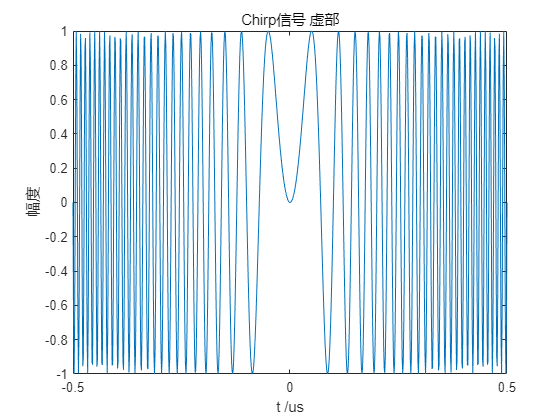

figure,plot( t*1e6, imag(st) ),xlabel('t /us'),ylabel('幅度'),title('Chirp信号 虚部');

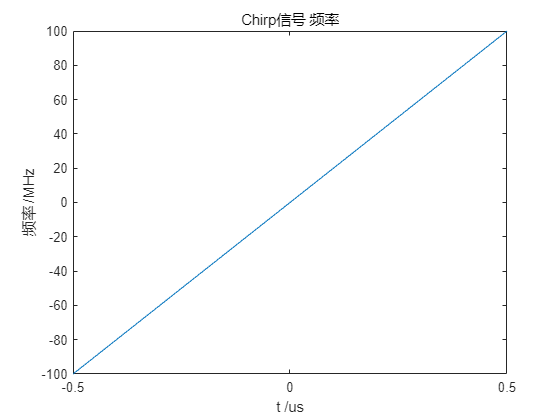

figure,plot( t*1e6, f*1e-6 ),xlabel('t /us'),ylabel('频率 /MHz'),title('Chirp信号 频率');

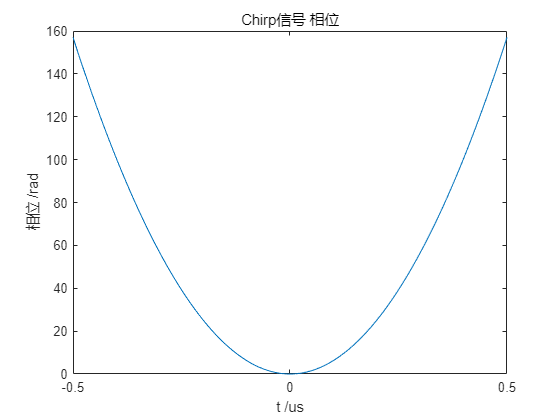

figure,plot( t*1e6, phase ),xlabel('t /us'),ylabel('相位 /rad'),title('Chirp信号 相位');

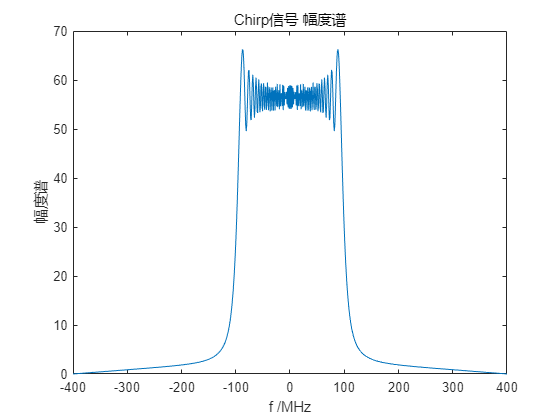

% 频域
figure,plot( freq*1e-6,abs(Sf) ),xlabel('f /MHz'),ylabel('幅度谱'),title('Chirp信号 幅度谱');

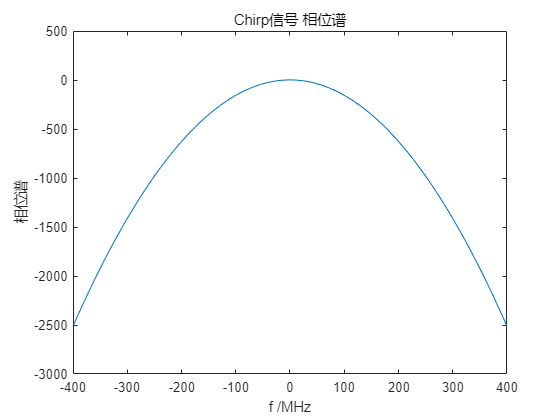

figure,plot( freq*1e-6,-pi*freq.^2/K+pi/4 ),xlabel('f /MHz'),ylabel('相位谱'),title('Chirp信号 相位谱');

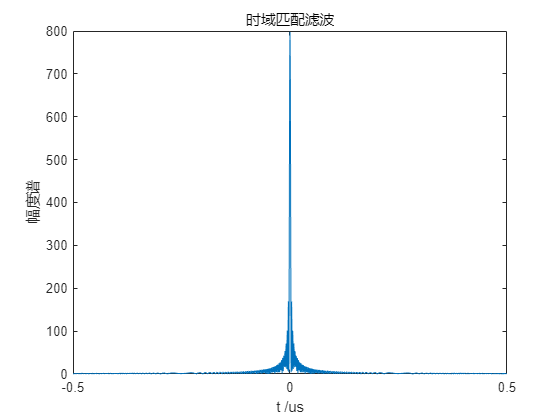

% 时域匹配滤波
figure,plot( t1*1e6 , abs(s1) ),xlabel('t /us'),ylabel('幅度谱'),title('时域匹配滤波');

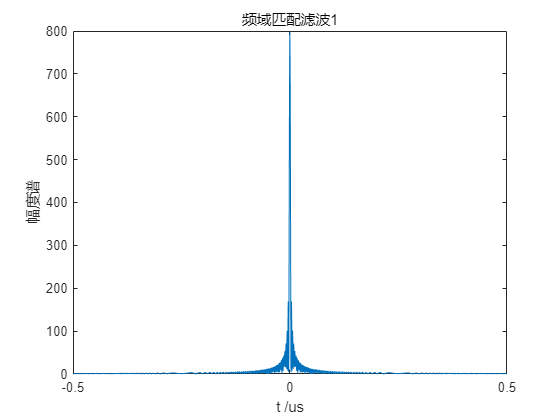

% 频域匹配滤波1
figure,plot( t2*1e6 , abs(s2) ),xlabel('t /us'),ylabel('幅度谱'),title('频域匹配滤波1');

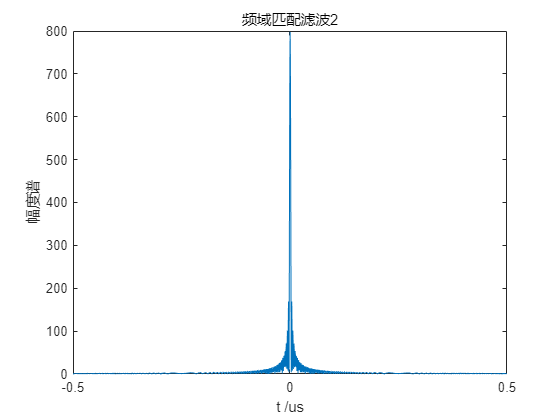

% 频域匹配滤波2
figure,plot( t2*1e6 , abs(s3) ),xlabel('t /us'),ylabel('幅度谱'),title('频域匹配滤波2');

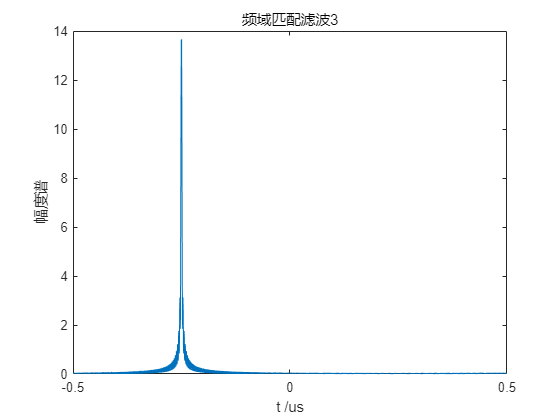

% 频域匹配滤波3
figure,plot( t2*1e6 , abs(s4) ),xlabel('t /us'),ylabel('幅度谱'),title('频域匹配滤波3');

## 利用匹配滤波器对回波信号进行脉冲压缩来测距

### 2个目标的回波信号的匹配滤波

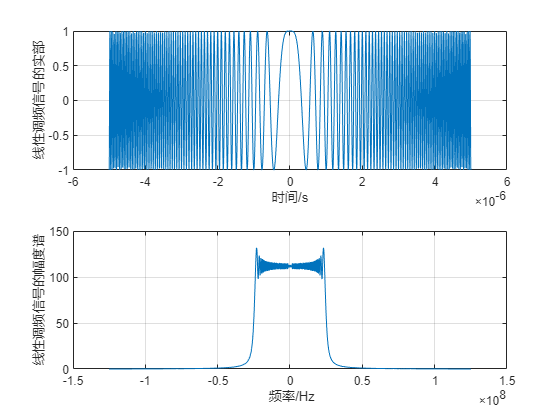

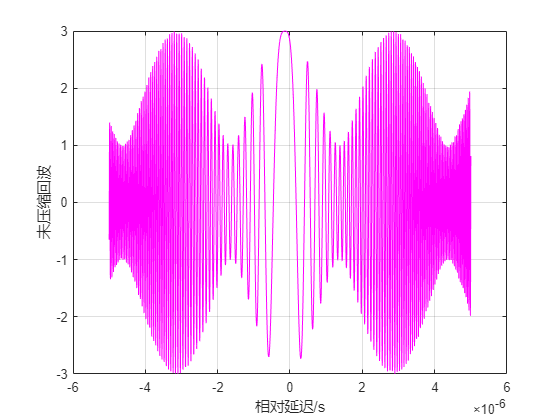

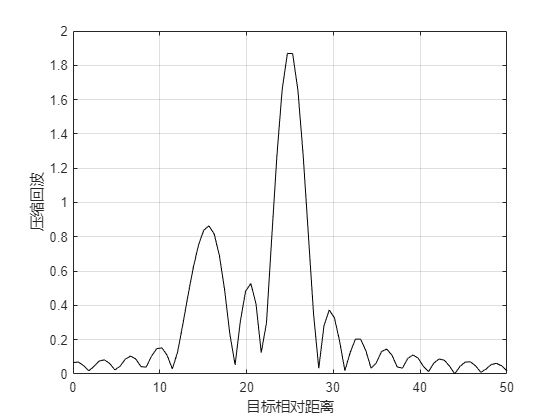

clear all;
close all;
clc;
%%调用matched_filter函数，观察结果，这两个目标回波是重叠的，不能被分辨，但是脉冲压缩后，这两个脉冲是完全分开的，即可以被分辨出来
nscat=2;             %两个目标
taup=10e-6;          %10us信号时宽
b=50.0e6;            %50MHz脉宽
rrec=50;             %50m的接收窗
scat_range=[15 25];  %目标的相对距离分别为15m、25米
scat_rcs=[1 2];      %目标的雷达截面积分别是1m^2和2m^2
winid=0;             %不加窗
[y]=matched_filter(nscat,taup,b,rrec,scat_range,scat_rcs,winid);

### 3个目标的回波信号的匹配滤波

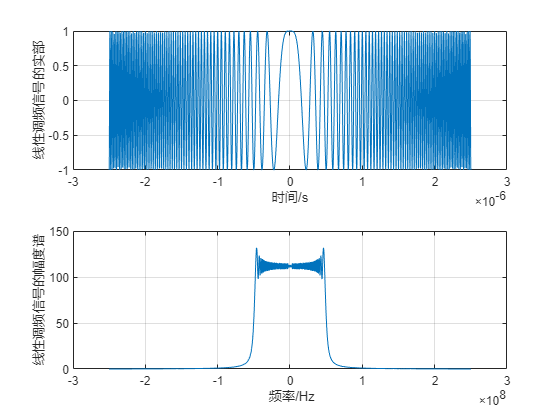

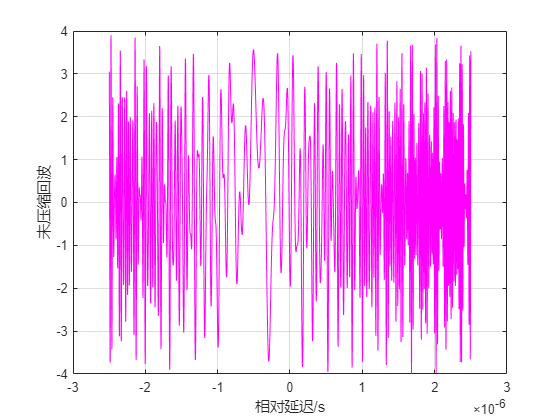

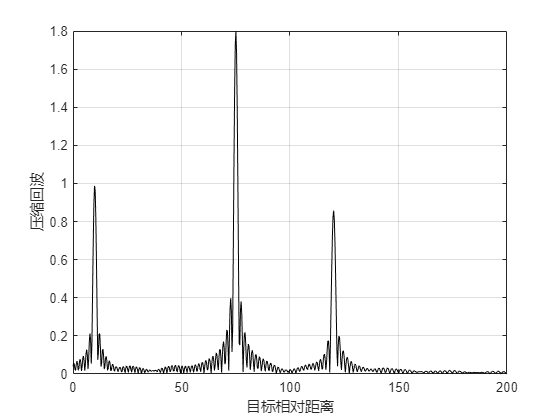

clear all;
close all;
clc;
%%%%%%%%%% 调用matched_filter函数观测3个目标相对距离为[10 75 120]m的结果 %%%%%%%%%%
nscat=3;                 %3个目标
taup=5e-6;               %5us非压缩脉冲
b=100e6;                 %100MHz脉宽
rrec=200;                %200m的处理窗
scat_range=[10 75 120];  %目标相对雷达的距离分别为10m、75m及120m
scat_rcs=[1 2 1];        %目标的雷达截面积分别是1m^2、2m^2及1m^2
winid=2;                 %凯泽窗
[y]=matched_filter(nscat,taup,b,rrec,scat_range,scat_rcs,winid);

function [y] =matched_filter(nscat,taup,b,rrec,scat_range,scat_rcs,winid)
%%------------------------------------------------------------------------------------------------------------%%
%%说明：使用匹配滤波器进行脉冲压缩，matched_filter函数的输出包括未压缩和压缩的信号图形，以及在脉冲压缩中使用的线性调频信号%%
%%------------------------------------------------------------------------------------------------------------%%
%********* y: 归一化的压缩输出 **************%
%***** nscat: 目标个数 *********************%
%****** taup: 信号时宽，单位为s *************%
%********* b: 信号带宽，单位为Hz ************%
%****** rrec: 接收窗的大小，单位为m *********%
% scat_range: 目标的相对距离向量，单位为m ****%
%** scat_rcs: 目标的雷达截面积向量，单位为m^2 %
%***** winid: 决定了选用什么样的滤波器形式 ***%  

%%%%% 时宽带宽积--time bandwidth product %%%%%
T_B_product=b*taup;
if(T_B_product<5)
    fprintf('**********Time Bandwidth product is TOO SMALL**********')
    fprintf('\nChange b and or taup');
    return
end

c=3e8;           %光速--speed of light
n=fix(5*taup*b); %采样点数--number of samples;函数fix()：向零方向取整
                 %根据奈奎斯特采样定理及频率分辨率△f=fs/N的要求可以确定采样点数N的取值

%%%%% 初始化输入输出--initialize input,output %%%%%
x(nscat,1:n)=0;
y(1:n)=0;
%%%%% 确定合适的接收窗--determine proper window %%%%%
if(winid==0)              %不加窗
    win(1:n)=1;
    win=win';  
else
    if(winid==1)          %汉明窗
        win=hamming(n);
    else
        if(winid==2)      %带参数pi的凯泽窗
           win=kaiser(n,pi);
        else
            if(winid==3)  %旁瓣为-60dB的切比雪夫窗
                win=chebwin(n,60);
            end
        end
    end
end
%%%%%% 确保目标在接收窗内--check to ensure that scatters are within receive window %%%%%
index=find(scat_range>rrec);
if(index~=0)
    fprintf('Error.Receive window is too large or scatters fall outside window');
    return
end
%%%%% 计算采样间隔--calculate sampling interval %%%%%
t=linspace(-taup/2,taup/2,n);
LFM=exp(1i*pi*(b/taup).*t.^2); %载频为0的线性调频信号

figure(1);
subplot(2,1,1);
plot(t,real(LFM));
xlabel('时间/s');
ylabel('线性调频信号的实部');
grid on;
subplot(2,1,2);
sampling_interval=taup/n;
freqlimit=1/sampling_interval;            %采样频率Fs=1/Ts
freq=linspace(-freqlimit/2,freqlimit/2,n);
plot(freq,fftshift(abs(fft(LFM))));
xlabel(' 频率/Hz');
ylabel('线性调频信号的幅度谱');
grid on;

for j=1:1:nscat
    range=scat_range(j);
    x(j,:)=scat_rcs(j).*exp(1i*pi*(b/taup).*(t+2*range/c).^2); %第j个目标的回波信号
    y=x(j,:)+y;                                                %实现对nscat个目标回波信号的叠加
end

figure(2);
plot(t,real(y),'m');
xlabel('相对延迟/s');
ylabel('未压缩回波');
grid on;

out=xcorr(LFM,y);       %xcorr(x,y):互相关函数
out=out./n;
s=taup*c/2;
Npoints=ceil(rrec*n/s); %ceil():朝正无穷方向取整
dist=linspace(0,rrec,Npoints);

figure(3);
plot(dist,abs(out(n:n+Npoints-1)),'k');
xlabel('目标相对距离');
ylabel('压缩回波');
grid on;
end
